# Panda Map Column

## Grid

grid = OctoGrid(2,2,2,10);

% add column
grid.addBox(0.9,1.25,0,0.2,0.2,1.5)

## Robot

% robot base transformation
Tbase = [cos(pi/2) -sin(pi/2) 0 0;
     sin(pi/2) cos(pi/2)  0 0;
     0          0           1 0;
     0          0           0 1]*eye(4);
Tbase(1:3,4) = [1,1,0]';

% set joints positions
joints = [0 0 0 0 0 0 0];

[robot_transforms] = GeometricPandaMATLAB(joints, Tbase);

## Show grid

% display
grid.showGridVol3D(grid.grid,'floor',true,'height',false)
hold on
axis equal
showPanda(robot_transforms,10)
hold off

## Generate trajectory

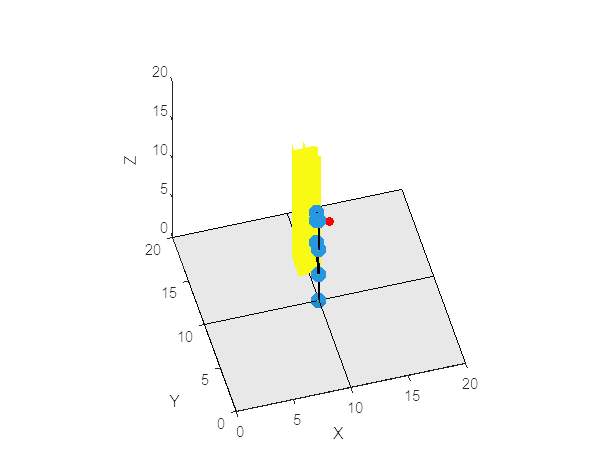

% trajectory generation points (xyz position, xyz angles)
control_points = [1 1.088 0.926 0 0 0;
                  1.2 1.4 0.5 0 0 0];

% Multiply the coordinates by 10 to scale the points
x = control_points(:, 1) * 10;
y = control_points(:, 2) * 10;
z = control_points(:, 3) * 10;

% display points
hold on

% Create a scatter plot with solid red points
scatter3(x, y, z, 'filled', 'MarkerFaceColor', 'red');

## Calculate motion plan using kinematics, ignoring obstacles

% calculate list of joints positions
[joints_positions_no_obstacles, EE_positions_no_obstacles, EE_distances] = kinematics_trajectory(control_points(2,:), Tbase, zeros(7,1))

J3 =     0.0000    0.5930    0.0000   -0.2770    0.0000    0.1070         0
    0.0880    0.0000    0.0880    0.0000    0.0880    0.0000         0
   -0.0000   -0.0880         0    0.0055         0    0.0880         0
         0         0         0         0         0         0         0
    0.0000    1.0000         0   -1.0000         0   -1.0000   -0.0000
    1.0000    0.0000    1.0000    0.0000    1.0000    0.0000   -1.0000


J3 =    -0.0126    0.5261    0.0065   -0.2469   -0.0217    0.1008    0.0000
    0.1032    0.0614   -0.0599   -0.0545    0.0613    0.0347    0.0000
         0   -0.1039    0.0002   -0.0698    0.0007    0.0885   -0.0000
   -0.0000   -0.1159    0.2989    0.2249   -0.1872    0.3343    0.0004
   -0.0000    0.9933    0.0349   -0.9737   -0.0783   -0.9424    0.0123
    1.0000    0.0000    0.9537   -0.0349    0.9792   -0.0115   -0.9999


J3 =    -0.0520    0.4455    0.0443   -0.2197   -0.0279    0.0936         0
    0.1146    0.2036   -0.0962   -0.1058    0.0515    0.0506         0
         0   -0.1259   -0.0002   -0.0890    0.0001    0.0887         0
    0.0000   -0.4157    0.4059    0.4381   -0.2237    0.4761    0.0051
    0.0000    0.9095    0.1855   -0.8989   -0.1223   -0.8794    0.0040
    1.0000    0.0000    0.8949   -0.0124    0.9669   -0.0011   -1.0000


J3 =    -0.0832    0.3883    0.0676   -0.2079   -0.0301    0.0909   -0.0000
    0.1345    0.2375   -0.1119   -0.1261    0.0498    0.0552   -0.0000
         0   -0.1581    0.0005   -0.0903   -0.0002    0.0887   -0.0000
   -0.0000   -0.5217    0.4880    0.5172   -0.2234    0.5166    0.0077
   -0.0000    0.8531    0.2985   -0.8558   -0.1308   -0.8562    0.0006
    1.0000    0.0000    0.8202    0.0037    0.9659    0.0035   -1.0000


J3 =    -0.1099    0.3507    0.0811   -0.2059   -0.0329    0.0897         0
    0.1597    0.2392   -0.1200   -0.1380    0.0520    0.0573         0
   -0.0000   -0.1938    0.0006   -0.0809   -0.0003    0.0887         0
    0.0000   -0.5634    0.5595    0.5538   -0.1995    0.5347    0.0086
    0.0000    0.8262    0.3816   -0.8326   -0.1203   -0.8450   -0.0007
    1.0000    0.0000    0.7357    0.0106    0.9725    0.0052   -1.0000


J3 =    -0.1332    0.3245    0.0884   -0.2100   -0.0366    0.0892         0
    0.1887    0.2288   -0.1256   -0.1459    0.0567    0.0581         0
    0.0000   -0.2310    0.0001   -0.0634   -0.0004    0.0887         0
    0.0000   -0.5763    0.6235    0.5682   -0.1586    0.5418    0.0088
   -0.0000    0.8173    0.4396   -0.8228   -0.0958   -0.8405   -0.0009
    1.0000   -0.0000    0.6466    0.0115    0.9827    0.0055   -1.0000


J3 =    -0.1533    0.3055    0.0915   -0.2179   -0.0407    0.0893   -0.0000
    0.2208    0.2132   -0.1305   -0.1505    0.0633    0.0579   -0.0000
    0.0000   -0.2688   -0.0006   -0.0395   -0.0004    0.0887   -0.0000
    0.0000   -0.5723    0.6808    0.5673   -0.1044    0.5405    0.0086
   -0.0000    0.8200    0.4751   -0.8235   -0.0609   -0.8413   -0.0006
    1.0000   -0.0000    0.5575    0.0091    0.9927    0.0052   -1.0000


J3 =    -0.1700    0.2910    0.0916   -0.2276   -0.0447    0.0899         0
    0.2555    0.1953   -0.1355   -0.1518    0.0711    0.0569         0
    0.0000   -0.3069   -0.0011   -0.0106   -0.0004    0.0887         0
    0.0000   -0.5572    0.7316    0.5547   -0.0396    0.5317    0.0083
    0.0000    0.8304    0.4909   -0.8321   -0.0196   -0.8469   -0.0001
    1.0000    0.0000    0.4731    0.0057    0.9990    0.0045   -1.0000


J3 =    -0.1831    0.2794    0.0893   -0.2375   -0.0480    0.0909    0.0000
    0.2922    0.1765   -0.1403   -0.1496    0.0797    0.0552    0.0000
   -0.0000   -0.3448   -0.0012    0.0221   -0.0003    0.0887   -0.0000
    0.0000   -0.5342    0.7758    0.5332    0.0333    0.5162    0.0078
    0.0000    0.8454    0.4903   -0.8460    0.0242   -0.8564    0.0006
    1.0000   -0.0000    0.3972    0.0027    0.9992    0.0036   -1.0000


J3 =    -0.1924    0.2696    0.0849   -0.2461   -0.0504    0.0923         0
    0.3305    0.1580   -0.1442   -0.1440    0.0885    0.0528         0
   -0.0000   -0.3824   -0.0010    0.0570   -0.0003    0.0888         0
    0.0000   -0.5056    0.8136    0.5053    0.1119    0.4947    0.0075
   -0.0000    0.8628    0.4768   -0.8630    0.0667   -0.8690    0.0012
    1.0000    0.0000    0.3328    0.0010    0.9915    0.0026   -1.0000


J3 =    -0.1979    0.2610    0.0787   -0.2524   -0.0515    0.0939         0
    0.3698    0.1401   -0.1463   -0.1353    0.0972    0.0499         0
    0.0000   -0.4194   -0.0005    0.0930   -0.0002    0.0888         0
    0.0000   -0.4729    0.8454    0.4728    0.1941    0.4680    0.0072
   -0.0000    0.8811    0.4538   -0.8812    0.1048   -0.8837    0.0018
    1.0000    0.0000    0.2818    0.0006    0.9754    0.0018   -1.0000


J3 =    -0.1994    0.2533    0.0707   -0.2558   -0.0513    0.0956         0
    0.4096    0.1232   -0.1454   -0.1242    0.1055    0.0466         0
         0   -0.4556    0.0001    0.1290   -0.0001    0.0888         0
    0.0000   -0.4374    0.8719    0.4372    0.2776    0.4369    0.0070
   -0.0000    0.8993    0.4241   -0.8994    0.1360   -0.8995    0.0022
    1.0000   -0.0000    0.2447    0.0010    0.9510    0.0011   -1.0000


J3 =    -0.1968    0.2462    0.0611   -0.2560   -0.0497    0.0974   -0.0000
    0.4495    0.1074   -0.1405   -0.1112    0.1131    0.0428   -0.0000
    0.0000   -0.4907    0.0007    0.1643   -0.0001    0.0888    0.0000
    0.0000   -0.3998    0.8938    0.3995    0.3607    0.4022    0.0069
    0.0000    0.9166    0.3899   -0.9167    0.1589   -0.9156    0.0025
    1.0000    0.0000    0.2214    0.0018    0.9191    0.0005   -1.0000


J3 =    -0.1902    0.2396    0.0504   -0.2528   -0.0469    0.0990         0
    0.4890    0.0927   -0.1309   -0.0971    0.1198    0.0388         0
         0   -0.5247    0.0010    0.1984   -0.0000    0.0888         0
    0.0000   -0.3607    0.9116    0.3602    0.4419    0.3645    0.0068
   -0.0000    0.9327    0.3526   -0.9329    0.1730   -0.9312    0.0026
    1.0000    0.0000    0.2111    0.0025    0.8802    0.0000   -1.0000


J3 =    -0.1797    0.2334    0.0389   -0.2463   -0.0430    0.1006         0
    0.5275    0.0790   -0.1158   -0.0825    0.1255    0.0345         0
   -0.0000   -0.5573    0.0011    0.2310    0.0000    0.0888         0
    0.0000   -0.3205    0.9255    0.3199    0.5201    0.3245    0.0068
   -0.0000    0.9473    0.3131   -0.9475    0.1781   -0.9459    0.0027
    1.0000    0.0000    0.2129    0.0029    0.8353   -0.0003   -1.0000


J3 =    -0.1653    0.2277    0.0272   -0.2366   -0.0383    0.1020         0
    0.5648    0.0662   -0.0943   -0.0679    0.1301    0.0300         0
    0.0000   -0.5885    0.0010    0.2620    0.0001    0.0888         0
    0.0000   -0.2792    0.9355    0.2785    0.5946    0.2827    0.0068
   -0.0000    0.9602    0.2720   -0.9604    0.1747   -0.9592    0.0026
    1.0000    0.0000    0.2257    0.0028    0.7848   -0.0006   -1.0000


J3 =    -0.1472    0.2223    0.0159   -0.2237   -0.0329    0.1033   -0.0000
    0.6003    0.0542   -0.0659   -0.0537    0.1335    0.0254    0.0000
    0.0000   -0.6181    0.0008    0.2915    0.0001    0.0888    0.0000
    0.0000   -0.2369    0.9410    0.2363    0.6647    0.2395    0.0068
    0.0000    0.9715    0.2294   -0.9717    0.1633   -0.9709    0.0026
    1.0000    0.0000    0.2489    0.0022    0.7290   -0.0008   -1.0000


hold on
plot3(EE_positions_no_obstacles(1,:)*10,EE_positions_no_obstacles(2,:)*10,EE_positions_no_obstacles(3,:)*10)

## Calculate obstacles repulsive field

## Calculate motion plan using kinematics, avoiding obstacles